# Lab 6 - Polynomial Interpolation

Name: Lilith Janevksa

## Problem 1

function [result] = MyLagrangeInterpolator(nodes_x,nodes_fx)
    Poly = @(x) 0;
    
    i = 0;
    while i < length(nodes_x)
        p = @(x) 1;
        
        i2 = 0;
            while i2 < length(nodes_x)
                if i2 == i
                    i2 = i2 + 1;
                    continue
                else
                    p = @(x) (p(x)).*((x-nodes_x(i2+1,1))/(nodes_x(i+1,1)-nodes_x(i2+1,1)));
                    i2 = i2 + 1;
                end
            end
        p = @(x) (nodes_fx(i+1,1))*(p(x));
        Poly = @(x) Poly(x)+p(x);
        i = i + 1;
    end

    result = Poly;
end

## Problem 2

i = 0;
while i<6
    


    nodes_x = -pi:2*pi/(i+3):pi;
    nodes_x = transpose(nodes_x(1,2:end-1));
    nodes_fx = cos(nodes_x);
    Poly = MyLagrangeInterpolator(nodes_x,nodes_fx);
    x = -pi:2*pi/1000:pi;
    y = Poly(x);
    plot(x,y,'Color',[0.2,0.0,0.0]+[0.8/6,0,0].*i,'LineWidth',1.7)
    hold on

    E = max(max(abs(cos(x)-Poly(x))))

    i = i + 1;
end
legend("n=1","n=2","n=3","n=4","n=5","n=6")
hold off

function [result] = MyLagrangeInterpolator(nodes_x,nodes_fx)
    Poly = @(x) 0;
    
    i = 0;
    while i < length(nodes_x)
        p = @(x) 1;
        
        i2 = 0;
            while i2 < length(nodes_x)
                if i2 == i
                    i2 = i2 + 1;
                    continue
                else
                    p = @(x) (p(x)).*((x-nodes_x(i2+1,1))/(nodes_x(i+1,1)-nodes_x(i2+1,1)));
                    i2 = i2 + 1;
                end
            end
        p = @(x) (nodes_fx(i+1,1)).*(p(x));
        Poly = @(x) Poly(x)+p(x);
        i = i + 1;
    end

    result = Poly;
end

Output:

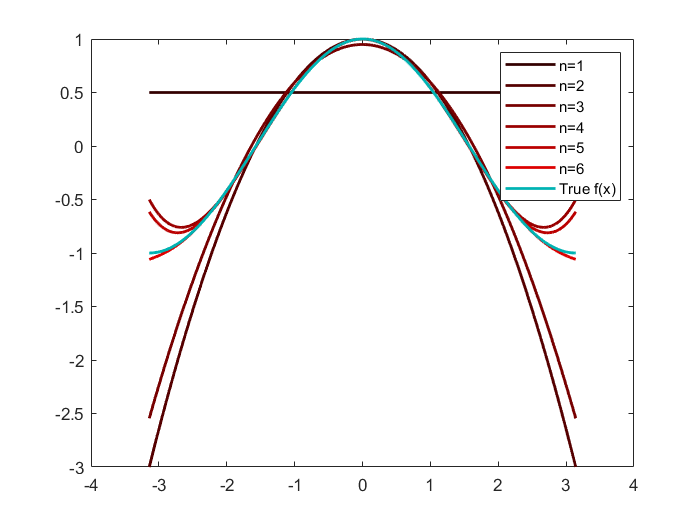

Maximum Errors:

E =

    1.5000


E =

     2


E =

    1.5451


E =

    0.5000


E =

    0.3847


E =

    0.0589

## Problem 3

#### a)

ans =

  153.2989

It's inbetween the prior and later value, so seems reasonable to me!

#### Part b)

ans =

  250.7360

Using my prior logic it seems reasonable, however, the difference between 1990 and 2000 is so small compared to the actual value that I'd say it's not perfectly reasonable. Better than nothing though!

It's not the best to try and find values outside of the interval of points we know, since the error will be much much much higher because you don't have any information to go off of.

## Problem 4

Output:

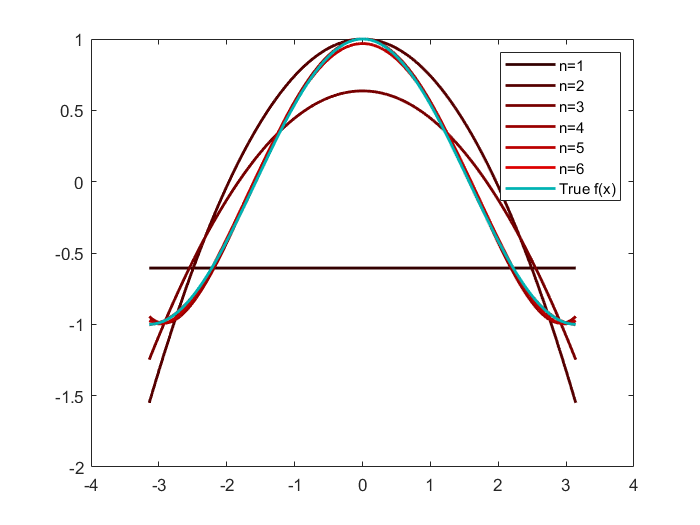

Errors:

E =

    1.6057


E =

    0.5503


E =

    0.3639


E =

    0.0555


E =

    0.0320


E =

    0.0027

## Problem 5

for i = 5:5:15

    nodes_x = -1:2/(i+3):1;
    nodes_x = transpose(nodes_x(1,2:end-1));
    nodes_fx = 1./(1+(4.*((nodes_x).^2)));
    Poly = MyLagrangeInterpolator(nodes_x,nodes_fx);
    x = -1:1/1000:1;
    y = Poly(x);
    plot(x,y,'Color',[0.2,0.0,0.0]+[0.8/15,0,0].*i,'LineWidth',1.7)
    hold on

    E = max(max(abs(1./(1+(4.*((x).^2)))-Poly(x))))

end
y = 1./(1+4.*((x).^2));
plot(x,y,'Color',[0,0.7,0.7],'LineWidth',1.7)
legend("n=5","n=10","n=15","True f(x)")
hold off

function [result] = MyLagrangeInterpolator(nodes_x,nodes_fx)
    Poly = @(x) 0;
    
    i = 0;
    while i < length(nodes_x)
        p = @(x) 1;
        
        i2 = 0;
            while i2 < length(nodes_x)
                if i2 == i
                    i2 = i2 + 1;
                    continue
                else
                    p = @(x) (p(x)).*((x-nodes_x(i2+1,1))/(nodes_x(i+1,1)-nodes_x(i2+1,1)));
                    i2 = i2 + 1;
                end
            end
        p = @(x) (nodes_fx(i+1,1)).*(p(x));
        Poly = @(x) Poly(x)+p(x);
        i = i + 1;
    end

    result = Poly;
end

### a)

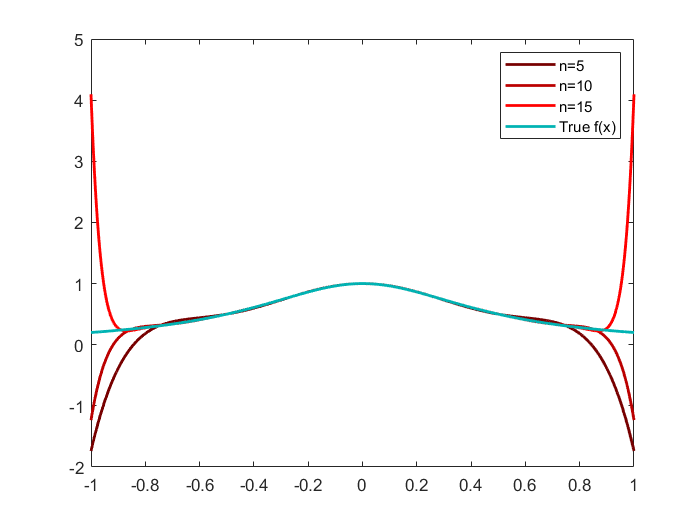

Errors:

E =

    2.2788


E =

    1.7741


E =

    3.5563

#### b) 

for i = 5:5:15

    nodes_x = [];
    i2 = 0;
    while i2 < i + 2    
        nodes_x = [nodes_x; cos((pi*((2*i2)+1))/(2*(i+2)))];
        i2 = i2 + 1;
    end
    nodes_fx = 1./(1+(4.*((nodes_x).^2)));
    Poly = MyLagrangeInterpolator(nodes_x,nodes_fx);
    x = -1:1/1000:1;
    y = Poly(x);
    plot(x,y,'Color',[0.2,0.0,0.0]+[0.8/15,0,0].*i,'LineWidth',1.7)
    hold on

    E = max(max(abs(cos(x)-Poly(x))))

end
y = 1./(1+4.*((x).^2));
plot(x,y,'Color',[0,0.7,0.7],'LineWidth',1.7)
legend("n=5","n=10","n=15","True f(x)")
hold off

function [result] = MyLagrangeInterpolator(nodes_x,nodes_fx)
    Poly = @(x) 0;
    
    i = 0;
    while i < length(nodes_x)
        p = @(x) 1;
        
        i2 = 0;
            while i2 < length(nodes_x)
                if i2 == i
                    i2 = i2 + 1;
                    continue
                else
                    p = @(x) (p(x)).*((x-nodes_x(i2+1,1))/(nodes_x(i+1,1)-nodes_x(i2+1,1)));
                    i2 = i2 + 1;
                end
            end
        p = @(x) (nodes_fx(i+1,1)).*(p(x));
        Poly = @(x) Poly(x)+p(x);
        i = i + 1;
    end

    result = Poly;
end

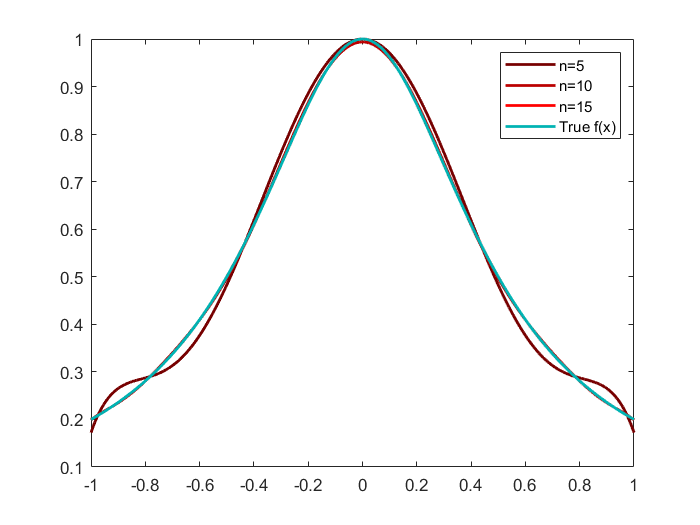

Errors:

E =

    0.4568


E =

    0.4249


E =

    0.4269

The error along the ends of the function were much better overall